% Parameters
learningRate = 0.0001;
BatchSize =  11

BatchSize = 11

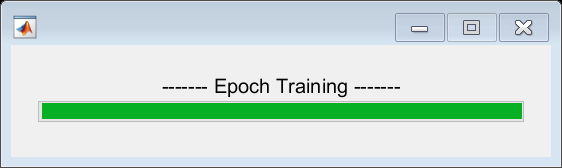

epochNum = 200;


% We have 60 images size 51x51x1
load('images.mat');
% and 3 possible classes
%1 = horizontal line
%2 = vertical line
%3 = circle
load('DesiredValuesVactor.mat');

%We want to prepare for a future EEG format for Freq x Time x Channel x Type (Power, Phase Angle, Phase Pref)
inpM = permute(inpM,[1 2 3 5 4]);
inputLayerSize = size(inpM);
outputLayerSize = length(unique(desV));

%Partition the data
cvp = cvpartition(desV,'HoldOut',0.2,'Stratify',true);
% extract the Training+Validation and Test data
trn_ind = training(cvp);
tst_ind = test(cvp);

TestData = inpM(:,:,:,:,tst_ind);
TestLabels = desV(tst_ind);
TrainData = inpM(:,:,:,:,trn_ind);
TrainLabels = desV(trn_ind);


%Determine number of folds for K fold and obtain partition
n_folds =10;
train_partitions = cvpartition(TrainLabels,'KFold',n_folds,'Stratify',true); % split data n times using Kfold
rng('shuffle');

for fold=1:n_folds

    %Network info
    % Convolutions are by Freq x Time x Channel x Type (Power, Phase Angle, Phase Pref)

    Network = CreateLayer([],'Input', [inputLayerSize(1:end-1)]); %Input Layer parameter is Size of one image
    Network = CreateLayer(Network,'Conv',[5 2 2 1 1],[1 2 2 1 1],[0 2]); % Convolution parameters are Filter [NumFilter x Imagesizes(1:4)],Max Pool Size, [Padding Stride]
    Network = CreateLayer(Network,'FC',[outputLayerSize]); % FC layer parameter are [OutputSize]
    Network = CreateLayer(Network,'Output',[outputLayerSize]);


    trn_ind = training(train_partitions,fold); % get training trial rows
    vld_ind = test(train_partitions,fold); % get test trial rows

    trn_dat = TrainData(:,:,:,:,trn_ind); % isolate training data
    vld_dat = TrainData(:,:,:,:,vld_ind); % isolate test data
    trn_cond = TrainLabels(trn_ind);
    vld_cond = TrainLabels(vld_ind);

    %------------------------------- Train -------------------------------
    H = waitbar(1,'------- Epoch Training -------');
    for j = 1:epochNum

       %Shuffle training data
       shufidx = randperm(size(trn_dat,5));
       trn_dat= trn_dat(:,:,:,:,shufidx);
       trn_cond = trn_cond(shufidx);

        BatchIti = size(trn_dat,5)/BatchSize;

        for B = 1:BatchIti

            batchimages = trn_dat(:,:,:,:,1+[[B-1]*BatchSize]:B*BatchSize);
            batchclass = trn_cond(1+[[B-1]*BatchSize]:B*BatchSize);

            for i = 1:BatchSize
                image =  batchimages(:,:,:,:,i);
                class =  batchclass(i) == unique(desV);

                %Calculate Forward and Predict Network
                OutNet(i,:) = ForwardModel(Network,image,class);
            end

            %Calculate Backpropogation and adjust Network
            Network = Backprop(OutNet,image,class,learningRate);
        end

        % Print the accuracy for the epoch
        [RMSE,Acc] = PredictModel(Network,vld_dat,vld_cond);
        
        X = ['Acc -  ',num2str(Acc), '; RMSE -  ', num2str(RMSE)];
        waitbar([1 - j/epochNum],H,X)
    end

    % ------------------------------- Test -------------------------------
    [RMSE,acc] = PredictModel(Network,TestData,TestLabels);
    disp("")
    disp(" -------------------- TEST -------------------- ")
    X = [num2str(j),'    Acc -  ',num2str(Acc), '    RMSE -  ', num2str(RMSE)];
    disp(X)
    fprintf(repmat('\b',1,length(X)))

end